Iteration 1 - Global Best Fitness: 0.087912
Iteration 2 - Global Best Fitness: 0.085714
Iteration 3 - Global Best Fitness: 0.083516
Iteration 4 - Global Best Fitness: 0.081319
Iteration 5 - Global Best Fitness: 0.076923
Iteration 6 - Global Best Fitness: 0.074725
Iteration 7 - Global Best Fitness: 0.072527
Iteration 8 - Global Best Fitness: 0.070330
Iteration 9 - Global Best Fitness: 0.065934
Iteration 10 - Global Best Fitness: 0.061538
Iteration 11 - Global Best Fitness: 0.057143
Iteration 12 - Global Best Fitness: 0.057143
Iteration 13 - Global Best Fitness: 0.054945
Iteration 14 - Global Best Fitness: 0.054945
Iteration 15 - Global Best Fitness: 0.054945
Iteration 16 - Global Best Fitness: 0.054945
Iteration 17 - Global Best Fitness: 0.054945
Iteration 18 - Global Best Fitness: 0.054945
Iteration 19 - Global Best Fitness: 0.054945
Iteration 20 - Global Best Fitness: 0.054945
Iteration 21 - Global Best Fitness: 0.054945
Iteration 22 - Global Best Fitness: 0.054945
Iteration 23 - Glob

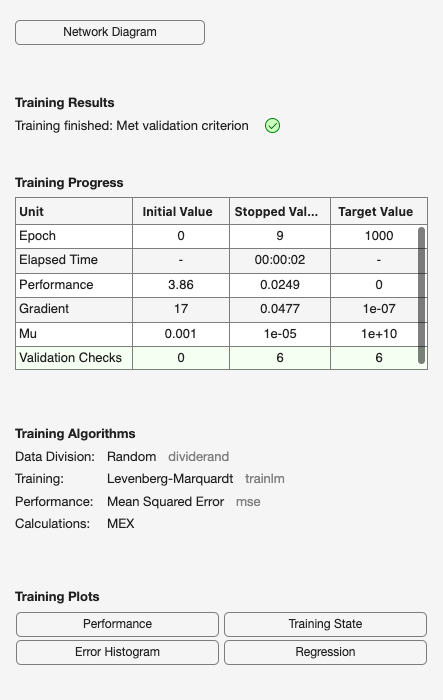

Iteration 1 - Global Best Fitness: 0.116484
Iteration 2 - Global Best Fitness: 0.070330
Iteration 3 - Global Best Fitness: 0.043956
Iteration 4 - Global Best Fitness: 0.043956
Iteration 5 - Global Best Fitness: 0.037363
Iteration 6 - Global Best Fitness: 0.037363
Iteration 7 - Global Best Fitness: 0.037363
Iteration 8 - Global Best Fitness: 0.037363
Iteration 9 - Global Best Fitness: 0.037363
Iteration 10 - Global Best Fitness: 0.028571
Iteration 11 - Global Best Fitness: 0.026374
Iteration 12 - Global Best Fitness: 0.026374
Iteration 13 - Global Best Fitness: 0.026374
Iteration 14 - Global Best Fitness: 0.026374
Iteration 15 - Global Best Fitness: 0.026374
Iteration 16 - Global Best Fitness: 0.026374
Iteration 17 - Global Best Fitness: 0.026374
Iteration 18 - Global Best Fitness: 0.026374
Iteration 19 - Global Best Fitness: 0.026374
Iteration 20 - Global Best Fitness: 0.026374
Iteration 21 - Global Best Fitness: 0.026374
Iteration 22 - Global Best Fitness: 0.026374
Iteration 23 - Glob

clear all; close all; clc;

% Nalaganje podatkov
file = load('data.mat'); % Load the data
data = file.data; % Assuming 'data' is the variable name in the .mat file

% Razdelimo podatke na razrede in značilke
labels = data(:, 1); % prvi stolpec so oznake razredov - labli
features = data(:, 2:end); % ostali stolpci so značilke

% Razdelimo delež nabora podatkov za testiranje 
testProportion = 0.2;
n = length(labels); % Total number of samples

% Naključno permutiramo podatke, da so random
perm = randperm(n);

% Točka deljenja
splitIndex = round((1 - testProportion) * n);

% Ureditev trening in testnih značilk in oznak
trainIndices = perm(1:splitIndex);
testIndices = perm(splitIndex+1:end);

trainData = data(trainIndices, :);
testData = data(testIndices, :);

% Razdelitev podatkov na trening in testni dataset
trainFeatures = trainData(:, 2:end)';
trainLabels = trainData(:, 1)'; % Pravilno nastavi stolpce za oznake
testFeatures = testData(:, 2:end)';
testLabels = testData(:, 1)'; % Pravilno nastavi stolpce za oznake

% Normalizacija podatkov, da je povprečje 0, std pa 1
[trainFeatures, mu, sigma] = zscore(trainFeatures'); % normaliziramo podatke na povprečje 0, standardni odklon 1
trainFeatures = trainFeatures';
testFeatures = (testFeatures' - mu) ./ sigma; % normiranje
testFeatures = testFeatures';

% Pretvorba oznak v binarno obliko (v binarne vektorje)
trainLabelsVec = ind2vec(trainLabels);
testLabelsVec = ind2vec(testLabels);

% PSO optimizacijska metoda
configs = {
    {[10, 7, 5], 'poslin', 'logsig'}; % 3 skriti sloji (10, 7, 5 nevroni) z 'poslin' in 'logsig'
    {[10, 7, 5], 'purelin', 'purelin'}; % 3 skriti sloji (10, 7, 5 nevroni) z 'purelin' in 'purelin'
};

results = table('Size', [length(configs), 7], ...
    'VariableTypes', {'string', 'string', 'string', 'double', 'double', 'double', 'double'}, ...
    'VariableNames', {'Config', 'HiddenLayers', 'HiddenFcn', 'TrainAccuracy', 'TestAccuracy', 'TrainAccuracyPSO', 'TestAccuracyPSO'});

for i = 1:length(configs)
    % konfiguracija posamezne nevronske mreže
    config = configs{i};
    hiddenLayerSizes = config{1}; % velikost skritih slojev
    hiddenTransferFcn = config{2}; % prenosna funkcija skritih slojev
    outputTransferFcn = config{3}; % prenosna funkcija izhodnega sloja

    % izgradnja dejanske nevronske mreže
    net = feedforwardnet(hiddenLayerSizes);
    % Nastavi prenosne funkcije za vse skrite sloje
    for j = 1:length(hiddenLayerSizes)
        net.layers{j}.transferFcn = hiddenTransferFcn;
    end
    % Nastavi prenosno funkcijo za izhodni sloj
    net.layers{length(hiddenLayerSizes) + 1}.transferFcn = outputTransferFcn;

    % Učenje mreže
    net = train(net, trainFeatures, trainLabelsVec);

    % napovedovanje razredov za trening in testne podatke
    predTrain = net(trainFeatures);
    predTest = net(testFeatures);

    % Pretvorba rezultatov v binarno obliko
    [~, predTrainClass] = max(predTrain, [], 1);
    [~, predTestClass] = max(predTest, [], 1);

    % Analiza rezultatov
    trainConfMat = confusionmat(vec2ind(trainLabelsVec), predTrainClass);
    testConfMat = confusionmat(vec2ind(testLabelsVec), predTestClass);

    % Izračun natančnosti
    trainAccuracy = sum(diag(trainConfMat)) / sum(trainConfMat(:));
    testAccuracy = sum(diag(testConfMat)) / sum(testConfMat(:));

    % PSO optimizacija
    [netPSO, global_best_fitness] = PSO_optimize(net, trainFeatures, trainLabelsVec, 30, 50, 0.9, 0.4, 0.9, 2.1, 2.1, 0.2, 0.05, 0.1);

    % Testiranje PSO optimizirane mreže
    predTrainPSO = netPSO(trainFeatures);
    predTestPSO = netPSO(testFeatures);

    % Pretvorba rezultatov v binarno obliko
    [~, predTrainClassPSO] = max(predTrainPSO, [], 1);
    [~, predTestClassPSO] = max(predTestPSO, [], 1);

    % Analiza rezultatov PSO
    trainConfMatPSO = confusionmat(vec2ind(trainLabelsVec), predTrainClassPSO);
    testConfMatPSO = confusionmat(vec2ind(testLabelsVec), predTestClassPSO);

    % Izračun natančnosti PSO
    trainAccuracyPSO = sum(diag(trainConfMatPSO)) / sum(trainConfMatPSO(:));
    testAccuracyPSO = sum(diag(testConfMatPSO)) / sum(testConfMatPSO(:));

    % Shranjevanje rezultatov v tabelo
    results.Config(i) = "Konfiguracija " + num2str(i);
    results.HiddenLayers(i) = mat2str(hiddenLayerSizes);
    results.HiddenFcn(i) = hiddenTransferFcn;
    results.TrainAccuracy(i) = trainAccuracy * 100;
    results.TestAccuracy(i) = testAccuracy * 100;
    results.TrainAccuracyPSO(i) = trainAccuracyPSO * 100;
    results.TestAccuracyPSO(i) = testAccuracyPSO * 100;
end


% Izpis vseh rezultatov na koncu
disp(results);

         Config          HiddenLayers    HiddenFcn    TrainAccuracy    TestAccuracy    TrainAccuracyPSO    TestAccuracyPSO
    _________________    ____________    _________    _____________    ____________    ________________    _______________

    "Konfiguracija 1"     "[10 7 5]"     "poslin"        37.363           36.842            94.505             90.351     
    "Konfiguracija 2"     "[10 7 5]"     "purelin"       95.385           96.491            98.022             96.491     




% Povprečna natančnost za linearne in nelinearne konfiguracije
linearConfigs = results(strcmp(results.HiddenFcn, 'purelin') | strcmp(results.HiddenFcn, 'poslin'), :);
nonlinearConfigs = results(~strcmp(results.HiddenFcn, 'purelin') & ~strcmp(results.HiddenFcn, 'poslin'), :);

avgTrainAccuracyLinear = mean(linearConfigs.TrainAccuracy);
avgTestAccuracyLinear = mean(linearConfigs.TestAccuracy);
avgTrainAccuracyLinearPSO = mean(linearConfigs.TrainAccuracyPSO);
avgTestAccuracyLinearPSO = mean(linearConfigs.TestAccuracyPSO);

avgTrainAccuracyNonlinear = mean(nonlinearConfigs.TrainAccuracy);
avgTestAccuracyNonlinear = mean(nonlinearConfigs.TestAccuracy);
avgTrainAccuracyNonlinearPSO = mean(nonlinearConfigs.TrainAccuracyPSO);
avgTestAccuracyNonlinearPSO = mean(nonlinearConfigs.TestAccuracyPSO);

fprintf('Povprečna natančnost (linearne aktivacije, učni podatki): %.2f%%\n', avgTrainAccuracyLinear);

Povprečna natančnost (linearne aktivacije, učni podatki): 66.37%


fprintf('Povprečna natančnost (linearne aktivacije, testni podatki): %.2f%%\n', avgTestAccuracyLinear);

Povprečna natančnost (linearne aktivacije, testni podatki): 66.67%


fprintf('Povprečna natančnost PSO (linearne aktivacije, učni podatki): %.2f%%\n', avgTrainAccuracyLinearPSO);

Povprečna natančnost PSO (linearne aktivacije, učni podatki): 96.26%


fprintf('Povprečna natančnost PSO (linearne aktivacije, testni podatki): %.2f%%\n', avgTestAccuracyLinearPSO);

Povprečna natančnost PSO (linearne aktivacije, testni podatki): 93.42%



fprintf('Povprečna natančnost (nelinearne aktivacije, učni podatki): %.2f%%\n', avgTrainAccuracyNonlinear);

Povprečna natančnost (nelinearne aktivacije, učni podatki): NaN%


fprintf('Povprečna natančnost (nelinearne aktivacije, testni podatki): %.2f%%\n', avgTestAccuracyNonlinear);

Povprečna natančnost (nelinearne aktivacije, testni podatki): NaN%


fprintf('Povprečna natančnost PSO (nelinearne aktivacije, učni podatki): %.2f%%\n', avgTrainAccuracyNonlinearPSO);

Povprečna natančnost PSO (nelinearne aktivacije, učni podatki): NaN%


fprintf('Povprečna natančnost PSO (nelinearne aktivacije, testni podatki): %.2f%%\n', avgTestAccuracyNonlinearPSO);

Povprečna natančnost PSO (nelinearne aktivacije, testni podatki): NaN%



% PSO optimization function

function [net, global_best_fitness] = PSO_optimize(net, X_train, Y_train, N_particles, N_iterations, w, w_min, w_max, c1, c2, v_max, mutation_rate, mutation_scale)
    % Initialize particles
    net_params = length(getwb(net));
    particle_positions = repmat(getwb(net)', N_particles, 1);
    particle_velocities = zeros(N_particles, net_params);
    particle_personal_bests = particle_positions;
    particle_personal_best_fitnesses = inf(N_particles, 1);
    global_best = particle_positions(1,:);
    global_best_fitness = inf;
    
    % Optimization loop
    for i = 1:N_iterations
        r1 = rand(size(particle_positions)); 
        r2 = rand(size(particle_positions));
        particle_velocities = w*particle_velocities + c1*r1.*(particle_personal_bests - particle_positions) + c2*r2.*(repmat(global_best, N_particles, 1) - particle_positions);
        
        % Apply velocity limits
        particle_velocities(particle_velocities > v_max) = v_max; 
        particle_velocities(particle_velocities < -v_max) = -v_max;
        
        % Update positions
        particle_positions = particle_positions + particle_velocities;
        
        % Apply mutations
        for j = 1:N_particles
            if rand < mutation_rate
                r = randn(1, size(particle_positions, 2));
                particle_positions(j,:) = particle_positions(j,:) + mutation_scale*(r/max(r));
            end
        end
        
        % Apply position limits
        particle_positions(particle_positions > 1) = 1; 
        particle_positions(particle_positions < -1) = -1;
        
        % Evaluate fitness
        particle_fitnesses = zeros(N_particles, 1);
        for j = 1:N_particles
            net = setwb(net, particle_positions(j,:)');
            outputs = net(X_train); % Using net to get the outputs
            errors = vec2ind(outputs) - vec2ind(Y_train); % Ensure correct calculation of errors
            particle_fitnesses(j) = sum(errors.^2) / numel(Y_train); % Correct fitness calculation
            
            % Update personal best
            if particle_fitnesses(j) < particle_personal_best_fitnesses(j)
                particle_personal_bests(j,:) = particle_positions(j,:);
                particle_personal_best_fitnesses(j) = particle_fitnesses(j);
            end
            
            % Update global best
            if particle_fitnesses(j) < global_best_fitness
                global_best = particle_positions(j,:);
                global_best_fitness = particle_fitnesses(j);
            end
        end
        
        % Update inertia weight
        w = max(w - (w_max - w_min) / N_iterations, w_min);
        fprintf("Iteration %d - Global Best Fitness: %f\n", i, global_best_fitness);
    end
    
    % Set network to best found weights
    net = setwb(net, global_best');
end
